# **FFT in matlab**

We aim to generate a sine wave in matlab with, for example, a single frequency of 20 Hz. The sine wave amplitude is **a. ** We now determine the sampling rate $f_s$ that should be higher than twice the frequency of signal (Nyquist theorem). You can use phase also for your sine signal as $y=sin(2\pi f t+\phi)$

f=20;     % frequency of sine wave
fs=40*f; %sampling frequency
phase = pi/4; % phase shift in radians
num_cycle = 4; % cycles of sine wave
a=0.3

a = 0.3000

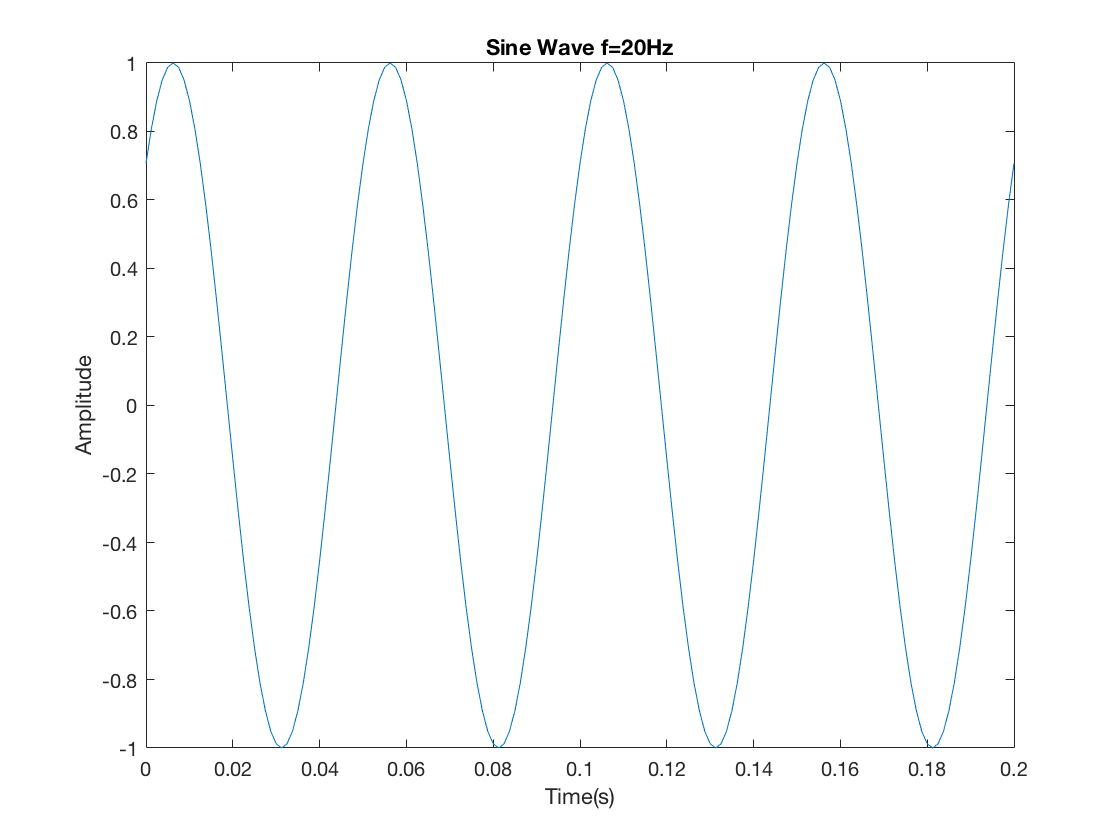

 
t=0:1/fs:num_cycle*1/f; %
 
y=sin(2*pi*f*t+phase); 
plot(t,x);
title(['Sine Wave f=', num2str(f), 'Hz']);
xlabel('Time(s)');
ylabel('Amplitude');

# **From time domain to frequency domain**

We carry out this transformation using Fast  Fourier Transform (FFT) which is an efficient implementation of Discrete Fourier Transform  (DFT). Typically, the number of points  is taken as power of 2 in the FFT computations.The DFT values are complex and we can plot then its amplitude to identify the frequency of our generated sine wave.

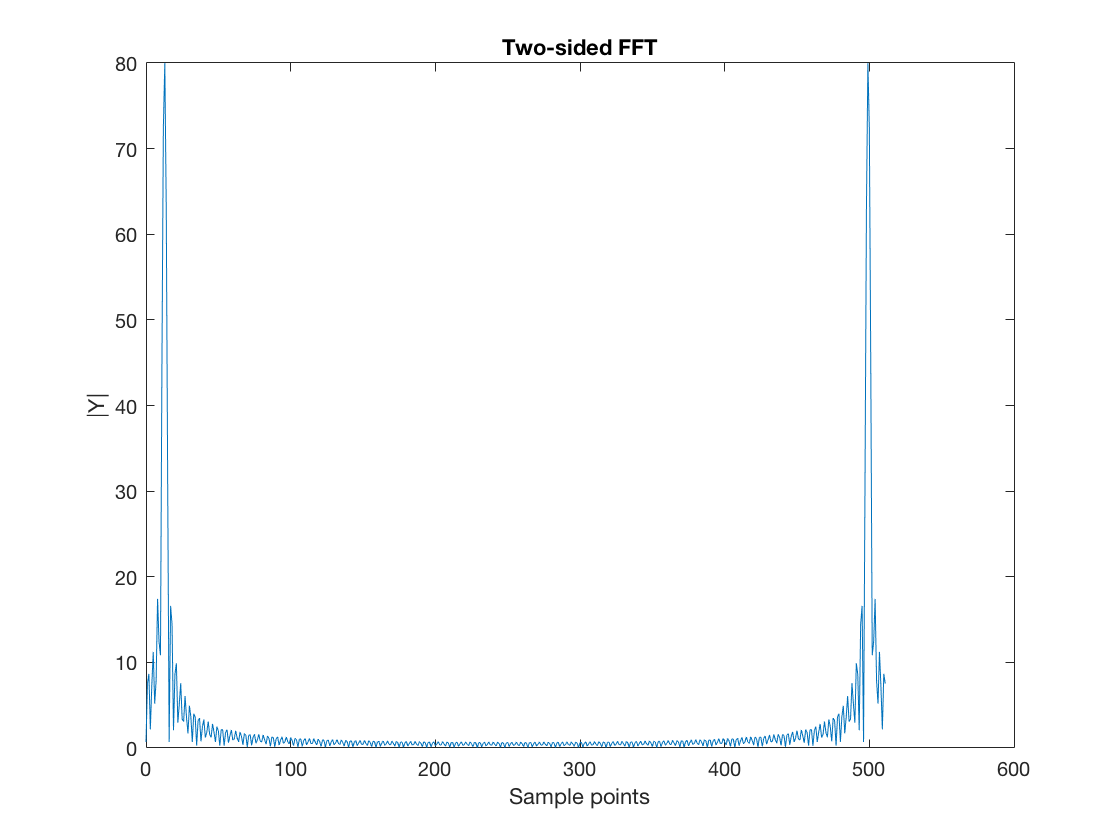

nfft=512; % number of points in DFT
Y=fft(x,nfft); % compute complex DFT using FFT
xvalues=0:nfft-1; % DFT sampling points
plot(xvalues,abs(Y));
title('Two-sided FFT');
xlabel('Sample points')
ylabel('|Y|');

We now focus on the accurate representations of x- and y-axis here. In order to extract the location of sine wave frequency on the x-axis we conduct a normalization over sampling points. First normalize the sampling points to unity: 


$$xvalues\leftarrow xvalues/nfft$$


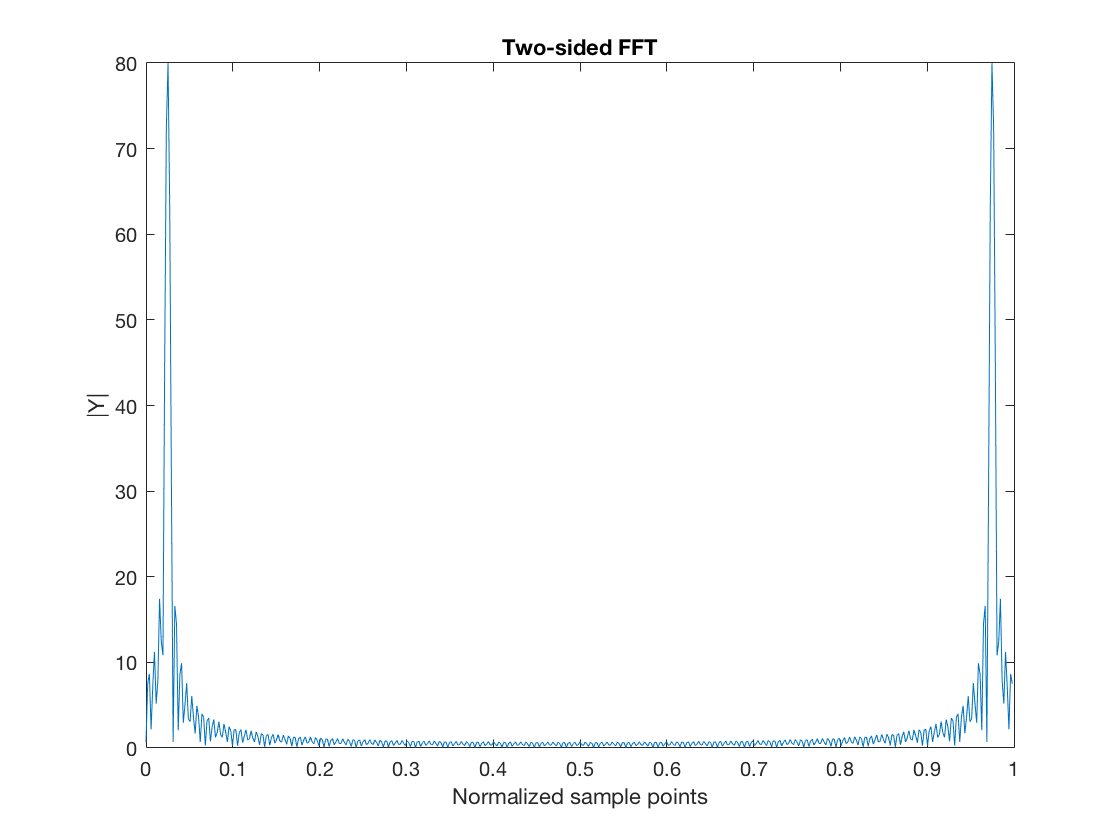

nfft=512; % number of points in DFT
X=fft(x,nfft); % compute complex DFT using FFT
xvalues=(0:nfft-1)/nfft; % DFT normalized sampling points
plot(xvalues,abs(X));
title('Two-sided FFT');
xlabel('Normalized sample points')
ylabel('|Y|');

The side lobes are due to spectral leakage.

As you observe, the values on x-axis are all positive and not representing the correct frequency on both positive  and negative frequency axes. We will center DFT values at the middle of x-axis by MATLAB $fftshift$


$$xvalues \leftarrow (-nfft/2:nfft/2-1)/nfft$$
 

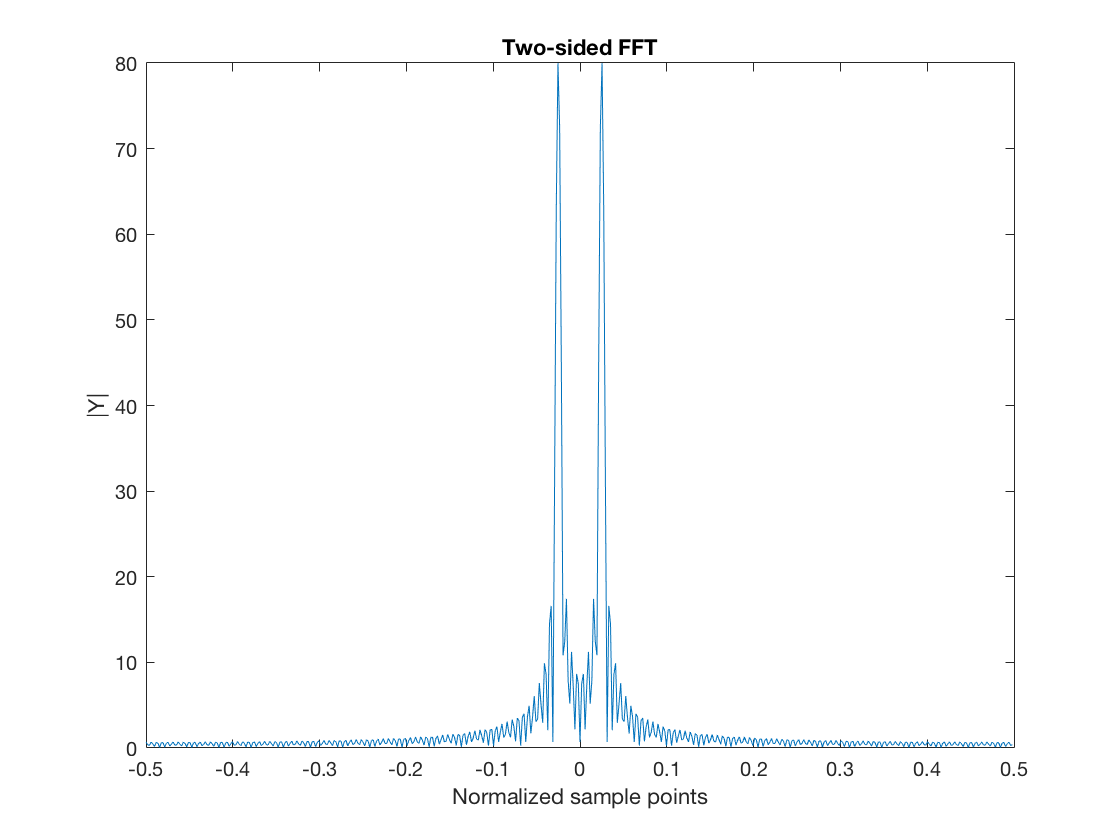

nfft=512; % number of points in DFT
Y=fftshift(fft(x,nfft)); % compute complex DFT using FFT
xvalues=(-nfft/2:nfft/2-1)/nfft; % DFT normalized sampling points
plot(xvalues,abs(Y));
title('Two-sided FFT');
xlabel('Normalized sample points')
ylabel('|Y|');

Still x-axis does not represent frequency in Hz. We can convert xvalues to frequency in Hz by


$$freq=f_s(-nfft/2:nfft/2-1)/nfft$$


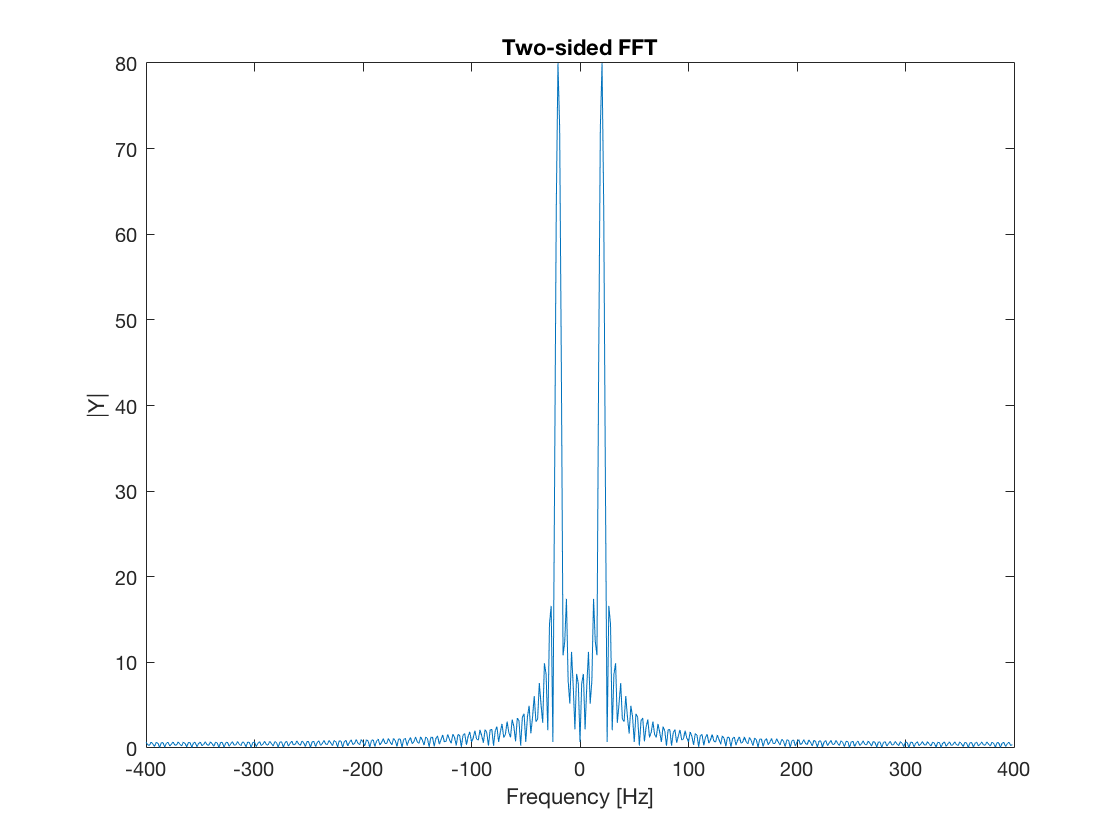

nfft=512; % number of points in DFT
Y=fftshift(fft(x,nfft)); % compute complex DFT using FFT
freq=fs*(-nfft/2:nfft/2-1)/nfft; %Frequency [Hz]
plot(freq,abs(Y));
title('Two-sided FFT');
xlabel('Frequency [Hz]')
ylabel('|Y|');

Vertical axis does not show the correct amplitude of signal which is $0.3$. To get it correct, we scale the vertical axis by proper scaling factor ( $1/nfft$) as


$$Y\leftarrow Y/nfft$$


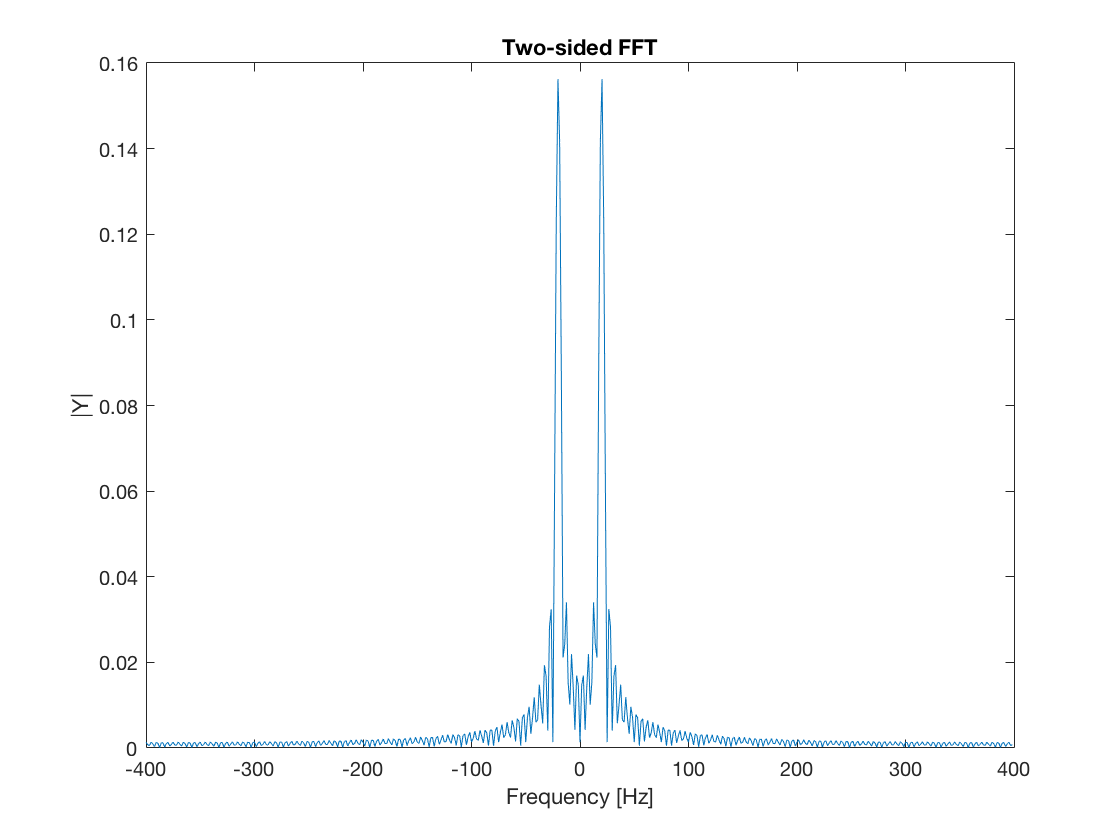

nfft=512; % number of points in DFT
Y=fftshift(fft(x,nfft))/nfft; % compute complex DFT using FFT
freq=fs*(-nfft/2:nfft/2-1)/nfft; % Frequency [Hz]
plot(freq,abs(Y));
title('Two-sided FFT');
xlabel('Frequency [Hz]')
ylabel('|Y|');

If you use scaling factor of $2/nfft$, you will have 

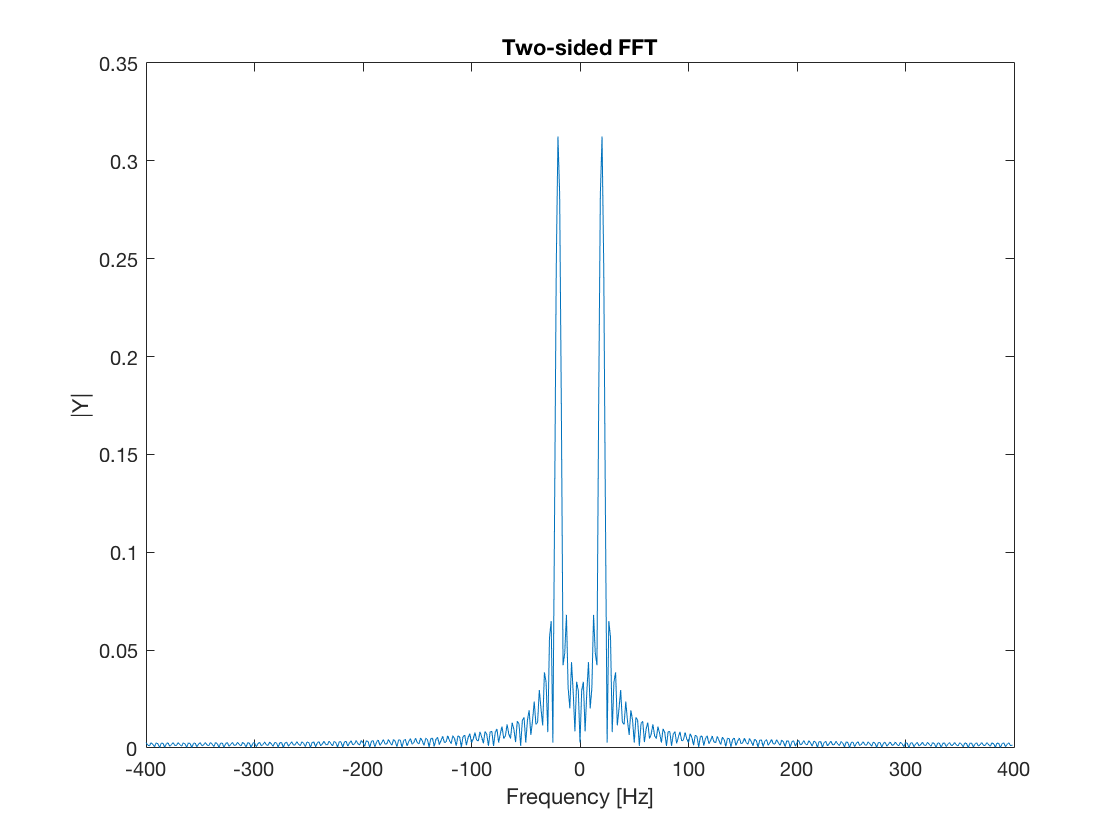

nfft=512; % number of points in DFT
Y=2*fftshift(fft(x,nfft))/nfft; % compute complex DFT using FFT
freq=fs*(-nfft/2:nfft/2-1)/nfft; % Frequency [Hz]
plot(freq,abs(Y));
title('Two-sided FFT');
xlabel('Frequency [Hz]')
ylabel('|Y|');